**Setting Up the Geometry**

H (rock depth) = 0.2m,    Nz (Points of the spatial Grid) = 100

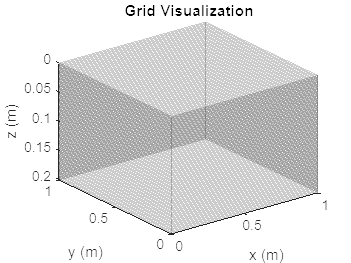

% Step 1: Define the Grid
Nx = 1; % Number of grid cells in the x-direction
Ny = 1; % Number of grid cells in the y-direction
Nz = 100; % Number of grid cells in the z-direction
H = 0.2; % Rock depth (in the z-direction)
Lx = 1; % Length of the domain (in the x-direction)
Ly = 1; % Length of the domain (in the x-direction)
% depth = linspace(0, H, Nz)';
G = cartGrid([Nx, Ny, Nz], [Lx, Ly, H]); % Grid with dimensions [Nx, Nz] in x-z plane

G = computeGeometry(G); % Compute geometry (cell volumes, centroids, face areas, etc.)


% Plot the grid
plotGrid(G, 'FaceColor', 'none', 'EdgeAlpha', 0.2); view(3);
xlabel('x (m)');
ylabel('y (m)');
zlabel('z (m)');
title('Grid Visualization');

**Define Rock and Fluid properties**

*Rock Properties:*

$\varphi_0 =0.3$,    $K_0 =0.02\textrm{∙}{10}^{-12} \ m^2$

*Fluid Properties:*

$\mu_w =\mu_o =0.001\ Pa\textrm{∙}s$,    $\rho_w =1000\frac{kg}{m^3 }$,    $\rho_o =660\frac{kg}{m^3 }$,    $k_{rw}^0 =k_{ro}^0 =1$

% Step 2: Define Fluid and Rock Properties
perm = repmat(0.02e-12, G.cells.num, 1); % Define initial absolute permeability
poro = 0.3; % Define porosity
rock = makeRock(G,perm,poro); %define intial absolute permeability and porosity
% plotCellData(G,rock.perm); view(3);

fluid = initSimpleADIFluid('mu', [0.001, 0.001], 'rho', [1000, 660]); % Define fluid properties